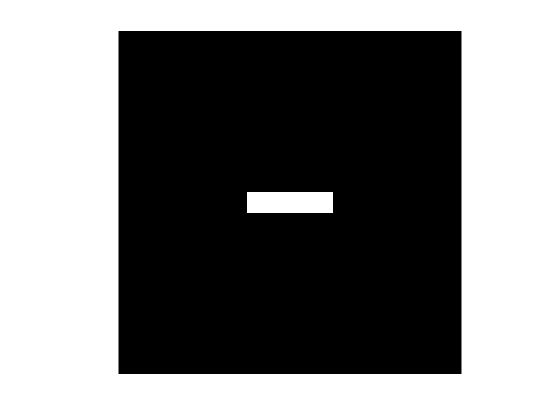

F = [zeros(60, 128); ones(8, 128); zeros(60, 128)] .* ... 
    [zeros(128, 48) ones(128, 32) zeros(128, 48)];

showgrey(F);

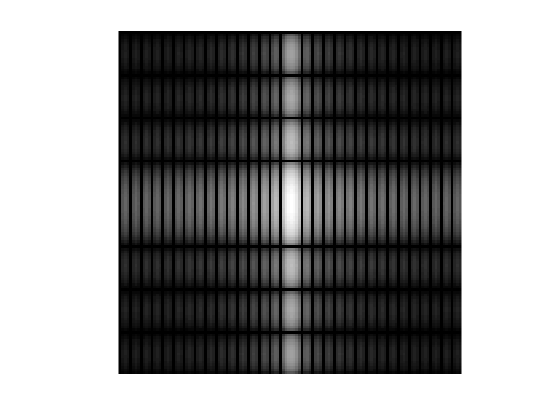


Fhat = fft2(F);
showfs(Fhat)

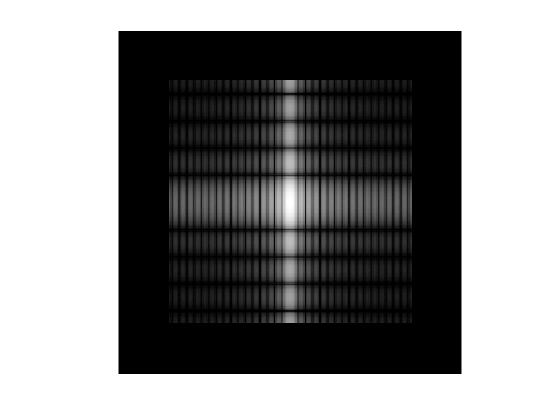


figure();
axis on;

showgrey(log(1 + abs(Hhat)))

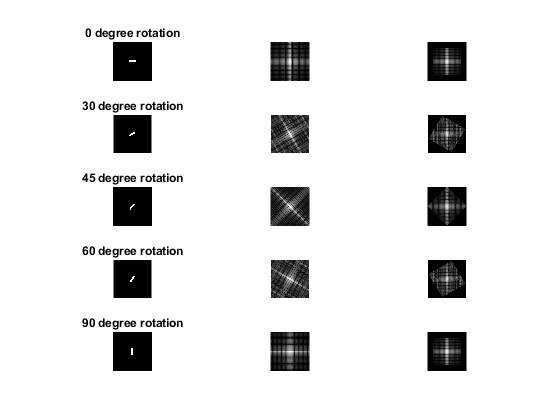

alphas = [0,30, 45, 60, 90];
imageCount = 1;
for i = 1:5
    subplot(5,3,imageCount);
    G = rot(F,alphas(i));
    Ghat = fft2(G);
    showgrey(G)
    title(sprintf('%d degree rotation',alphas(i)));
    imageCount=imageCount+1;
    subplot(5,3,imageCount);
    showfs(Ghat);
    imageCount=imageCount+1;
    subplot(5,3,imageCount);
    Hhat = rot(fftshift(Ghat),-alphas(i));
    showgrey(log(1+abs(Hhat)));
    imageCount=imageCount+1;
end